# Fitting the parametrization of a manifold

## Generating synthetic data

We first generate 3-dimensional data that is constrained to a lower-dimensional manifold. We generate a set of points along the surface of the unit sphere. These points can be parametrized as 


$$x = \sin \theta \cos \varphi \\
y = \sin \theta \sin \varphi \\
z = \cos \theta 
 $$


Our goal is to parametrize this surface around the point $\left(0,0,-1\right)$ as a graph over its tangent space. The tangent space is given as the $x-y$ plane. Note, however that this graph style parametrization is only valid locally, away from the points where the sphere folds over the tangent space. We therefore restrict the angles to $\varphi \in \left\lbrack 0,2\;\pi \;\right\rbrack ,\theta \in \left\lbrack -\pi ,-\frac{\;3}{4}\pi \;\right\rbrack \ldotp$

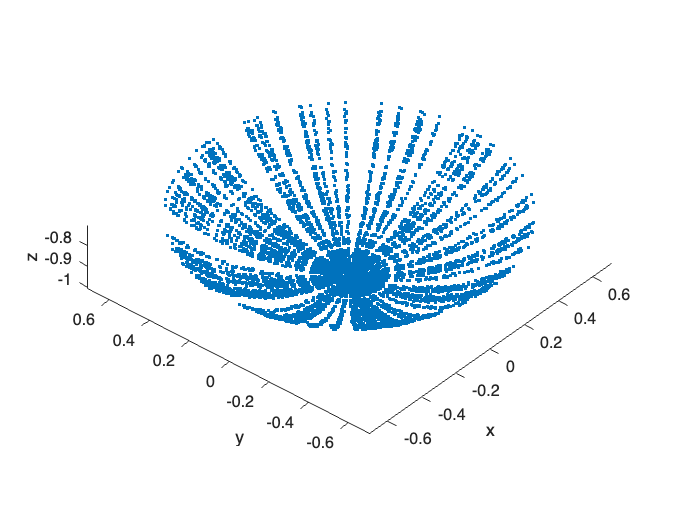

clear all; 
close all;

Npoints = 100;
rng(0)
phi = 2*pi*rand(Npoints, 1);
theta = -pi + (pi/4) * rand(Npoints, 1);
[Phi, Theta] = meshgrid(phi,theta);
Phi = Phi(:);
Theta = Theta(:);
% we generate points on the surface of the sphere. 
X = sin(Theta).*cos(Phi);
Y = sin(Theta).*sin(Phi);
Z = cos(Theta);

% Add artificial small noise to the data
noise_magnitude = 1e-2;
X = X + (rand(numel(X), 1)-0.5) * noise_magnitude;
Y = Y + (rand(numel(Y), 1)-0.5) * noise_magnitude;
Z = Z + (rand(numel(Z), 1)-0.5) * noise_magnitude;
plot3(X, Y, Z, '.')
axis equal
xlabel('x')
ylabel('y')
zlabel('z')

## Setting up the variables for fitting the geometry

In this case, the synthetic data does not come from a dynamical system and we are only interested in fitting a two-dimensional manifold to this cloud of points. 

We prepare a cell array that is compatible with SSMLearn.

% the {j, 1} entry contains the time axis normally. We don't need it now 
yData{1,1} = linspace(1,10000, 10000);

% the observables are entered in column-wise
yData{1,2} = [X'; Y'; Z'];

% need to ensure that the data is centered. In this case we know that we
% have to add 1 to the Z components
yData{1,2}(3,:) = yData{1,2}(3,:) + 1.;

SSMDim = 2;
% the order of the SSM can be 
SSMOrder = 4;
IMInfo = IMGeometry(yData, SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.738061e-05    4.441e-16    1.800e-04
    1       2    1.727370e-05    3.253e-08    1.681e-04    3.340e-04
    2       3    1.682560e-05    7.583e-07    1.104e-04    1.608e-03
    3       4    1.612929e-05    1.273e-05    7.131e-05    6.568e-03
    4      10    1.612573e-05    1.977e-08    7.316e-05    2.640e-04
    5      11    1.608656e-05    2.971e-07    7.916e-05    1.174e-03
    6      12    1.589018e-05    8.638e-06    1.088e-04    6.366e-03
    7      13    1.572177e-05    3.585e-05    2.481e-04    1.360e-02
    8      14    1.552617e-05    2.497e-05    3.011e-04    1.272e-02
    9      15    1.519940e-05    1.442e-05    2.591e-04    1.240e-02
   10      16    1.486454e-05    1.605e-06    1.928e-04    3.599e-03
   11      17    1.443274e-05    1.725e-06    2.289e-04    2.239e-03
   12      18    1.385646e-05    2.357e-06    2

We have successfully fitted a polynomial expression  ${\bf y}={\bf V}{\mathbf{u}}+\sum_{|\mathbf{k}|=2}^{n_{\mathrm{SSM}}}{\bf W}_{\mathbf{k}}{\mathbf{u}}^{\mathbf{k}}$.

The reduced coordinates can be recovered as $\mathbf{u} = \mathbf{V}^T \mathbf{y}$

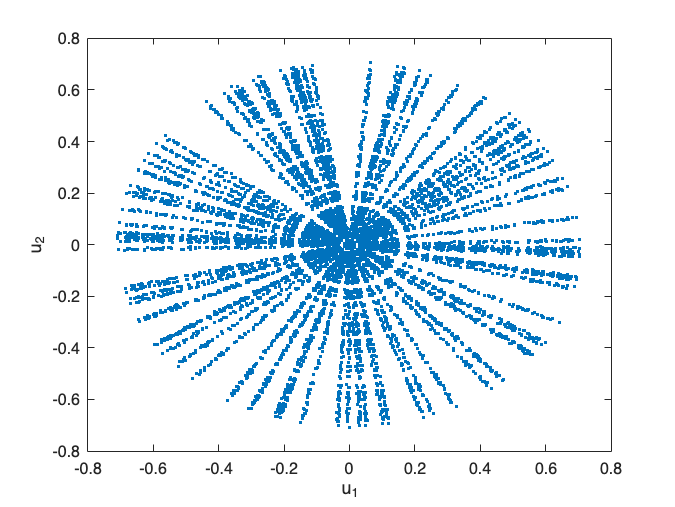

figure();
uData = IMInfo.chart.map(yData{1,2});
plot(uData(1,:), uData(2,:), '.');
xlabel('u_1')
ylabel('u_2')

## Visualizing the surface

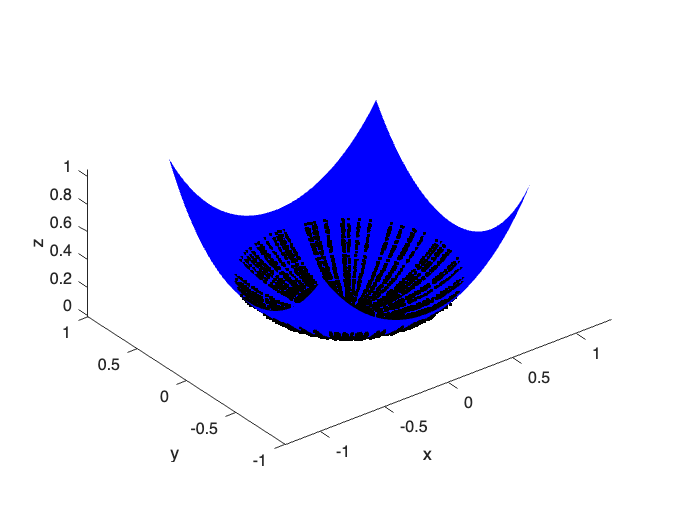

u1 = linspace(-0.8, 0.8, 100);
u2 = linspace(-0.8, 0.8, 100);
[U1, U2] = meshgrid(u1, u2);
uPlot = [U1(:)'; U2(:)'];
yPlot = IMInfo.parametrization.map(uPlot); % this is equivalent to 
%yPlot = IMInfo.parametrization.tangentSpaceAtOrigin * uPlot + IMInfo.parametrization.nonlinearCoefficients * IMInfo.parametrization.phi(uPlot); 

T = delaunay(U1, U2);
figure();
shading interp;
hold on;
trisurf(T, yPlot(1,:), yPlot(2,:), yPlot(3,:),'EdgeColor','none','FaceColor','blue');
axis equal;
plot3(yData{1,2}(1,:), yData{1,2}(2,:), yData{1,2}(3,:), '.', 'Color', 'black');
view(3);
xlabel('x')
ylabel('y')
zlabel('z')

This visualization can be more compactly writte using the built in functions of SSMLearn.

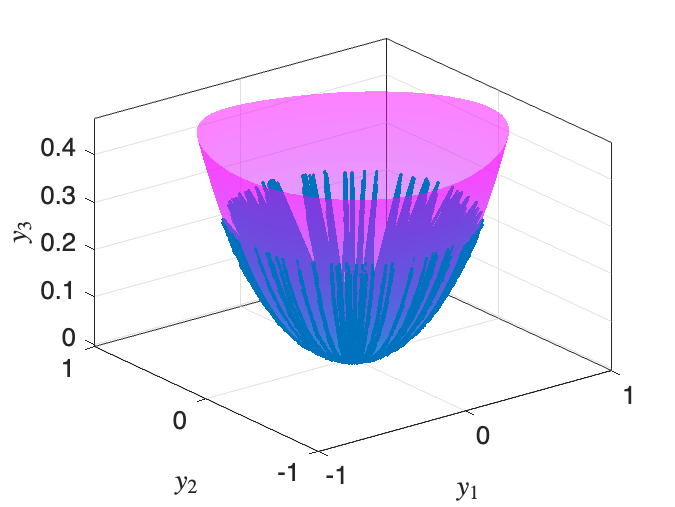

plotSSMWithTrajectories(IMInfo, [1, 2, 3], yData);